%% Clear3 workspace
clear; close all; clc;

% firmware v0.37
%% Define Pluto SDR device IP addresses clearly
% pluto0_IP = 'ip:192.168.2.1';  % Pluto SDR #1 (Default IP)
% pluto1_IP = 'ip:192.168.2.2';  % Pluto SDR #2 (Custom IP)
pluto0_ID = 'usb:0'; % 'usb:2.10.5'; 192.168.2.1 - red
pluto1_ID = 'usb:1'; % 'usb:2.6.5';  192.168.2.2 - green

% ~/CodeProjects/libiio/build/ iio_info -a | grep fw_version
% Multiple contexts found. Please select one using --uri:
	% 0: 0456:b673 (Analog Devices Inc. PlutoSDR (ADALM-PLUTO)), serial=10447318ac0f0009f3ff1a00ee49180db1 [usb:2.6.5]
	% 1: 0456:b673 (Analog Devices Inc. PlutoSDR (ADALM-PLUTO)), serial=10447318ac0f001006000200cd52173ac3 [usb:2.10.5]
%% Clearly specify USB IDs obtained from iio_info
% pluto0_ID = 'usb:2.6.5';  192.168.2.2
% pluto1_ID = 'usb:2.10.5'; 192.168.2.1

%% RF Parameters
fc = 2441e6;    % Center frequency: 2.441 GHz (Wi-Fi/Bluetooth)
fs = 10e6;      % Sampling frequency: 10 MHz (practical stability)
fftSize = 4096; % FFT size for visualization clarity
freqAxis = (-fftSize/2:fftSize/2-1)*(fs/fftSize) + fc;

%% Pluto SDR #0 (TX only)
txPluto0 = sdrtx('Pluto', ...
    'RadioID', pluto0_ID, ...
    'CenterFrequency', fc, ...
    'BasebandSampleRate', fs, ...
    'Gain', -5);

%% Pluto SDR #1 (RX only)
rxPluto1 = sdrrx('Pluto', ...
    'RadioID', pluto1_ID, ...
    'CenterFrequency', fc, ...
    'BasebandSampleRate', fs, ...
    'GainSource', 'Manual', ...
    'Gain', 30, ...
    'SamplesPerFrame', fftSize);

%% Identify Pluto SDR devices with visual and audio indication
disp('Identifying Pluto SDR Devices...');

Identifying Pluto SDR Devices...



% Device 0 indication
disp('Flashing Pluto #0 (IP:192.168.2.1)');

Flashing Pluto #0 (IP:192.168.2.1)


beep; pause(0.2); beep;

% Device 1 indication
disp('Flashing Pluto #1 (IP:192.168.2.2)');

Flashing Pluto #1 (IP:192.168.2.2)


beep; pause(0.2); beep; pause(0.2); beep; 
beep; pause(0.2); beep; pause(0.2); beep;

disp('Device identification complete.');

Device identification complete.



%% Helper function for TX waveform
generateTone = @(f, nSamples, fs) exp(2j*pi*f*(0:nSamples-1)'/fs);

%% Visualization Setup
specData = zeros(100, fftSize);
timeAxis = (1:100)*(fftSize/fs);

figure('Name', 'Pluto SDR TX/RX Spectrogram', 'NumberTitle', 'off');

%% Start Transmission and Reception Loop
disp('Starting TX from Pluto #0 and RX on Pluto #1...');

Starting TX from Pluto #0 and RX on Pluto #1...


transmitRepeat(txPluto0, generateTone(1e6, fftSize, fs)); % TX a continuous 1MHz tone from Pluto #1

## Establishing connection to hardware. This process can take several seconds.
## Waveform transmission has started successfully and will repeat indefinitely. 
## Call the release method to stop the transmission.


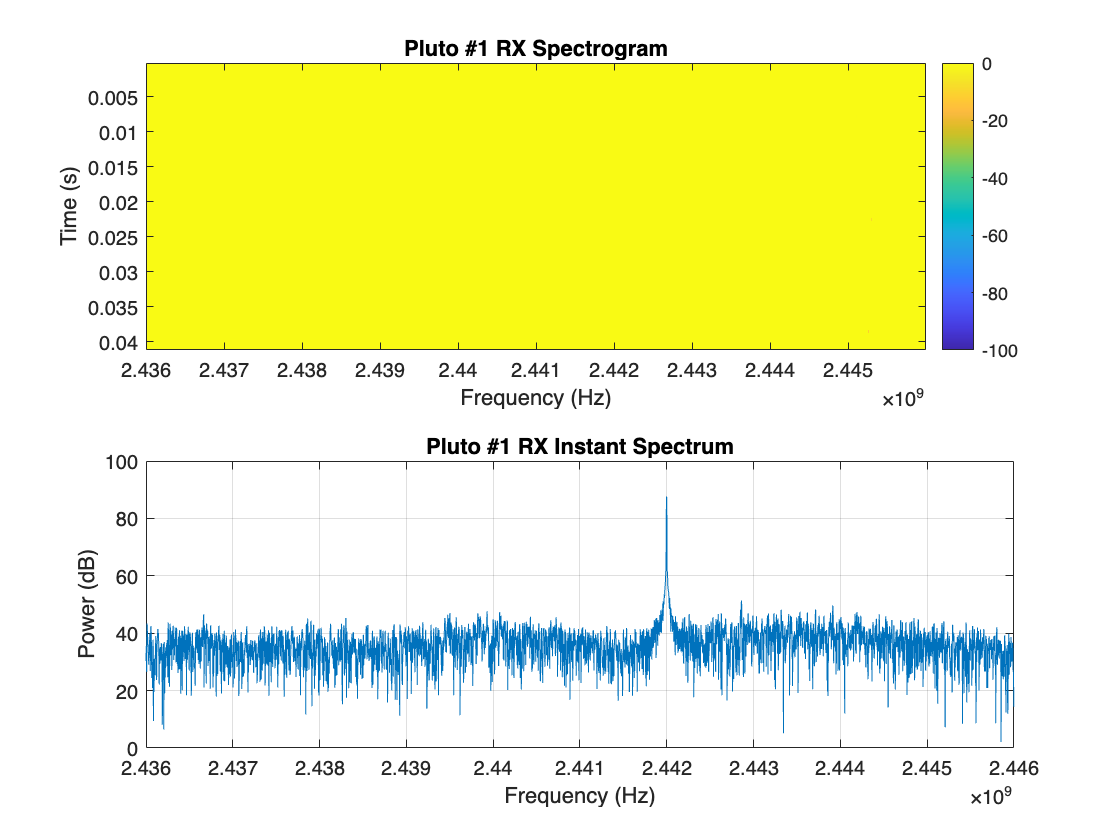

## Establishing connection to hardware. This process can take several seconds.



tic;
for k = 1:100
    % Receive samples from Pluto #1
    rxSamples = double(rxPluto1());

    % Compute FFT spectrum clearly
    spectrum = fftshift(fft(rxSamples .* blackman(fftSize)));
    powerDb = 10*log10(abs(spectrum).^2);

    % Update spectrogram matrix
    specData = [specData(2:end,:); powerDb'];

    % Plot Spectrogram (RX Pluto #1)
    subplot(2,1,1)
    imagesc(freqAxis, timeAxis, specData);
    title('Pluto #1 RX Spectrogram');
    xlabel('Frequency (Hz)');
    ylabel('Time (s)');
    clim([-100 0]);
    colorbar;

    % Plot FFT Spectrum (Instantaneous, RX Pluto #1)
    subplot(2,1,2)
    plot(freqAxis, powerDb);
    title('Pluto #1 RX Instant Spectrum');
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    grid on;

    drawnow;
end

toc;

Elapsed time is 8.794760 seconds.



%% Clean up Pluto SDR resources
release(txPluto0);
release(rxPluto1);

disp('Transmission and reception completed.');

Transmission and reception completed.
